# Multivariate Linear Regression

clear

## Data Loading and Preprocessing

#### Removal of non-numerical elements

The data shown describes how the miles per gallon (MPG) relates to the various characteristics of a car, such as the number of cylinders, the displacement (cubic in.), the horsepower, the weight (lbs.), and the acceleration (from 0 to 60 mph in seconds). Thus, each of these characteristics are the independent variable and the MPG is the dependent variable. We now have a data set with multiple features, and these five features dictate how the car performance in terms of MPG is.

(Data obtained from Mathworks [Sample Data Sets](https://www.mathworks.com/help/stats/sample-data-sets.html). You can download any of these data sets, by going to the MATLAB Drive, load the data set you want to download, and then copy and paste the data set to a folder in your computer.)

data = load("carbig.mat")

This command displays the data set.

cars = struct2table(data,"AsArray",false)

If you want to take a look at a specific cell value, you can call the cell like this.

cars(1,4)

If you want to save the numerical value to a variable, then you use the curly brackets instead.

chevy_cylinders = cars{1,4}

This command saves the data file to a csv file, which we will use for Python.

% writetable(cars,"carbig.csv")

Let's clean the data and remove the rows with non-numerical values. This command looks at the values of the columns with numerical values. Note that the output is now an array.

vars = ["Acceleration","Cylinders","Displacement","Horsepower","Weight","MPG"];
carbig = cars{:,vars}

We assign the number of rows and columns to the variables *row* and *col*.

[row,col] = size(carbig)

This command takes a look at the elements with NaN values. If it **is NaN** (isnan), then the output value is 1. Otherwise, the output is zero.

isnan(carbig)

Now, we can look for the row indices corresponding to the outputs with 1's, because these are the rows with elements NaN. When you scroll down, you can see these indices are missing. These indices correspond to the elements of MPG without NaN values. However, they are flattened, which is why you see index numbers that are larger than the row numbers.

idx_temp = find(isnan(carbig))

To unflatten the indices, we divide each of the indices by the number of rows. The remainder will give us the row number in the column that they belong to. We don't care about the column numbers, but only care about the row numbers. Here are now the row numbers we want removed from our table. 

r = sort(mod(idx_temp,row))

We now delete these rows from the array *carbig*.

carbig(r,:) = [];

Display output as a table.

cars = array2table(carbig,"VariableNames",vars)

Plot the MPG agains the 5 features.

clf
reset(gcf)
clear pos
for i = 1:5
    subplot(1,5,i)
    scatter(cars{:,i},cars{:,6})
    xlabel(['', cars.Properties.VariableNames{i}])
    ylabel("MPG")
end
pos = get(gcf,"Position");
set(gcf,"Position",pos+[1000 0 1000 0])

#### Feature Scaling

Feature scaling ensures that the convergence to the minimum is quicker by making sure the features are in the same order of magnitude or in a similar scale. The idea is get every feature into approximately the $-1\le x\le 1$range or order.

We determine the number of rows, $m$, and the number of columns, $n$.

[m,n] = size(carbig)

The, we do a feature scaling on the input features.

carbig(:,1:n-1) = FeatureScale(carbig(:,1:n-1))

#### Adding the bias column

Let's add the column corresponding to the coefficient of $\theta_0$. We'll call this column the Bias column, for reasons that will be obvious later when we discuss neural networks. The values of this column, $x_0$, are all ones. It needs to have the same number of rows as the variable *cars_clean_data*. 

cars_clean_data = [ones(m,1) carbig]

This part displays the transposed data set. 

% cars_temp = cars_clean_data';
% vars_row = ["Bias" "Acceleration" "Cylinders" "Displacement" "Horsepower" "Weight" "MPG"];
% array2table(cars_temp,"RowNames",vars_row)

## Implementation of the Gradient Descent Method

We now define an initial value for the parameter, $\theta$. 

theta = [20;1;-1;2;3;0.1];

We also set the first six columns as the input data set and the last column as the expected output.

x = cars_clean_data(:,1:6);
y = cars_clean_data(:,7);

Furthermore, let's define the options for the gradient descent, i.e. the learning rate and the number of epochs.

epochs = 1e4;
learning_rate = 0.001;

Let's run the function $gradient\_descent$. This function first solves for the gradient based on the parameter, $\theta$, and then uses this gradient to obtain new values of the $\theta$. It does this for several epochs. The final value of $\theta$ after all epochs is assigned to the variable $opt\_theta$ and displayed.

[opt_theta, Jcost] = gradient_descent(x,y,theta,learning_rate,epochs);
opt_theta

The cost function per epoch is displayed in this figure.

figure
plot(Jcost,'o')
xlabel('Number of iterations')
ylabel('Cost')

#### Expected Result

We solve for the expected result for $\theta$ using the $fitlm$ function.

model = fitlm(cars);
theta = model.Coefficients.Estimate

## Comparing with the Actual Values

Since this is a multivariate linear regression problem, our equation for the line is given by


$$Y=\theta_{\textrm{bias}} +\theta_{\textrm{Acceleration}} X_{\textrm{Acceleration}} +\theta_{\textrm{Cylinders}} X_{\textrm{Cylinders}} +\theta_{\textrm{Displacement}} X_{\textrm{Dsiplacement}} +\theta_{\textrm{Horsepower}} X_{\textrm{Horsepower}} +\theta_{\textrm{Weight}} X_{\textrm{Weight}}$$


To translate this into code, we recall that our theta parameters is a $6\times 1$ matrix and that our input and output parameters is the variable *cars* and is a $392\times 6$ matrix. We remove the output parameter, which is the last column and then add a first column with unit values, which will be our bias column. We assign the result to the variable $X$.

X = cars(:,1:5);
len = size(cars)
X = [array2table(ones(len(1),1),"VariableNames","Bias") X]

Thus, to get the output $Y$, we simply multiply the matrix, $\theta$, by the matrix, $X$, i.e.


$$Y=X^T \cdot \theta^T =\theta X$$


Y = X{:,1}*opt_theta(1) + X{:,i+1}*opt_theta(i+1);

## Using the Regression Learner App

MATLAB has a built-in Regression Learner App, where you don't actually need to code. But you do need to prepare the data set first. Earlier, we open the file 'carbig.mat', saved it in the variable *data*, and then converted the structured data set to a table, and assigned the output to the variable 'cars.' This is the data set that we are going to use in this example.

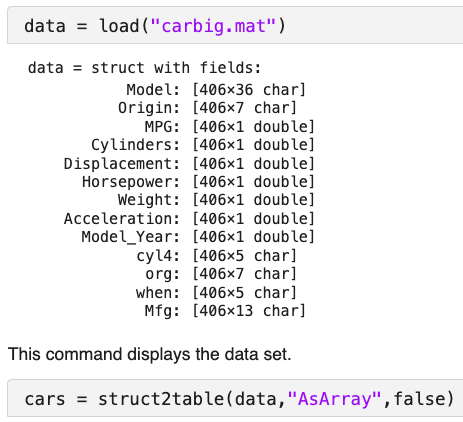

In the Menu bar, under APPS, select the 'Regression Learner' app. 

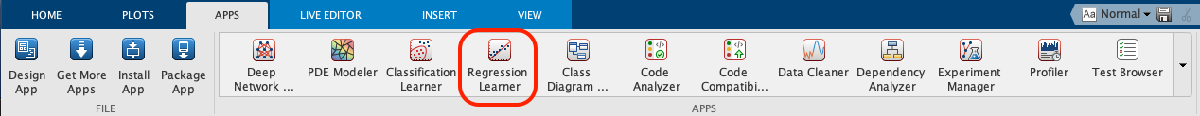

The Regression Learner window will open and will look like this.

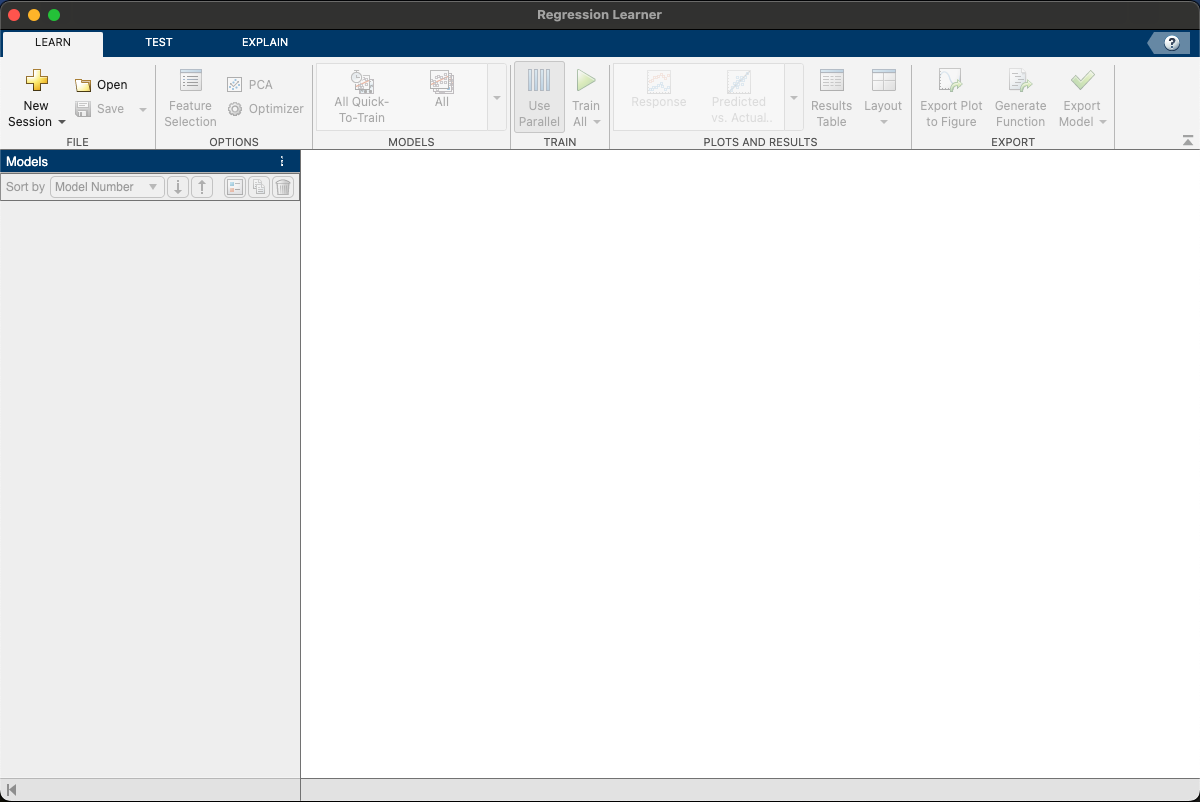

In the Menu bar, under LEARN, click the New Session button. You will see that you need to choose between loading the data 'From Workspace' or 'From File'. In our case, since we have already loaded onto the Workspace, we select 'From Workspace.' 

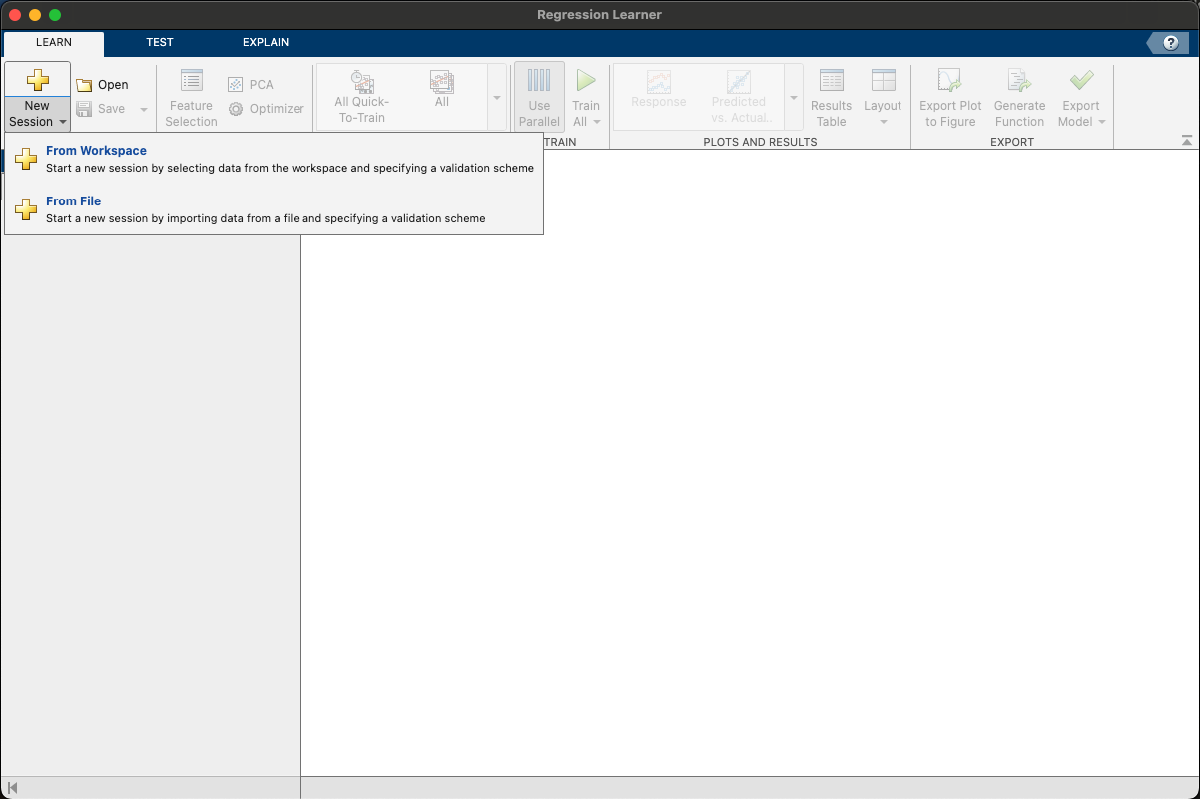

Another window will pop up and will look like this. Click the 'Select Input' dropdown menu to select the input variables or the Predictors.

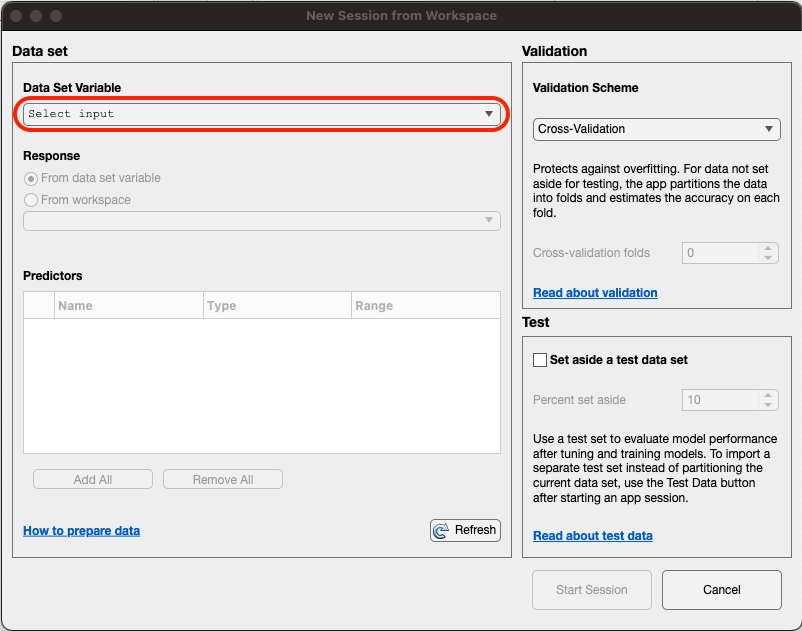

Which data should we select? In the drop down menu, we select that data set 'cars'. We observe that there are five Predictors that have been loaded - the Acceleration, the Cylinders, the Displacement, the Horsepower, and the Weight. The Response variable is automatically selected to be the last column in the data set. You can also select it from the workspace. Leave the default values of Validation Scheme parameters. You may select a number of test data set by clicking the tick box 'Set aside a test data set' and typing in a value in percent for the test data. The default value is 10%. 

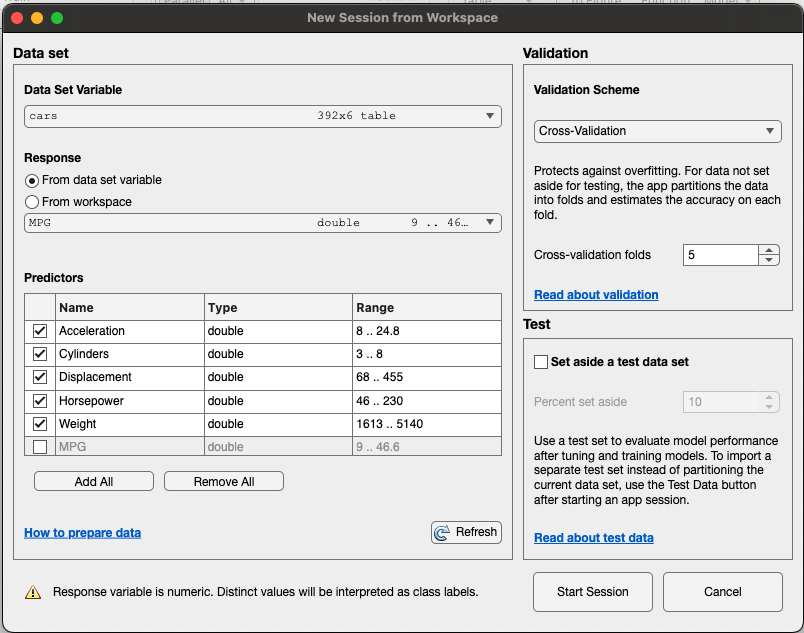

Once done, click the button 'Start Session'. You will then see this window. The default training model the Decision Tree. Since this is a regression problem with multiple inputs, we select the linear regression model. In the MODELS pane, click the drop down arrow. You will see four Linear Regression models and one button, 'All Linear', to select all four models to train with. Click the 'All Linear' button.

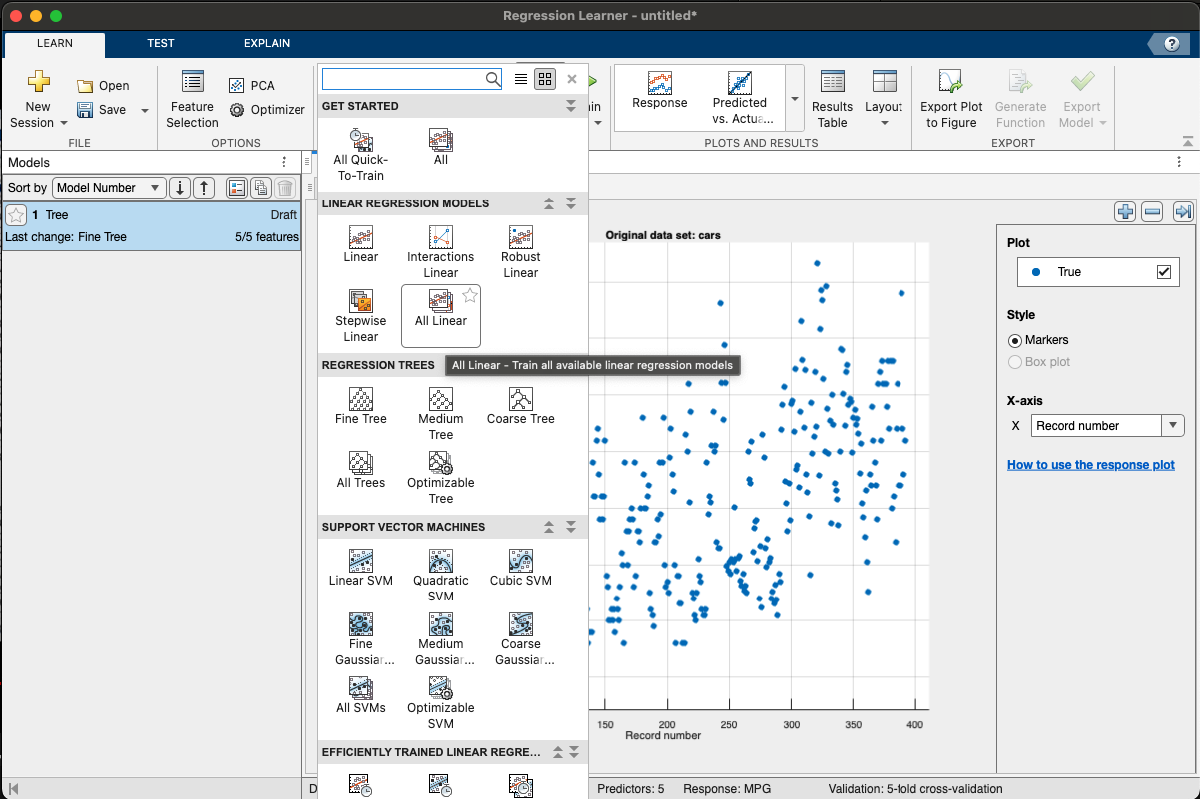

In the TRAIN pane, click the drop down arrow and then click the 'Train All' button to train with all four linear regression models.

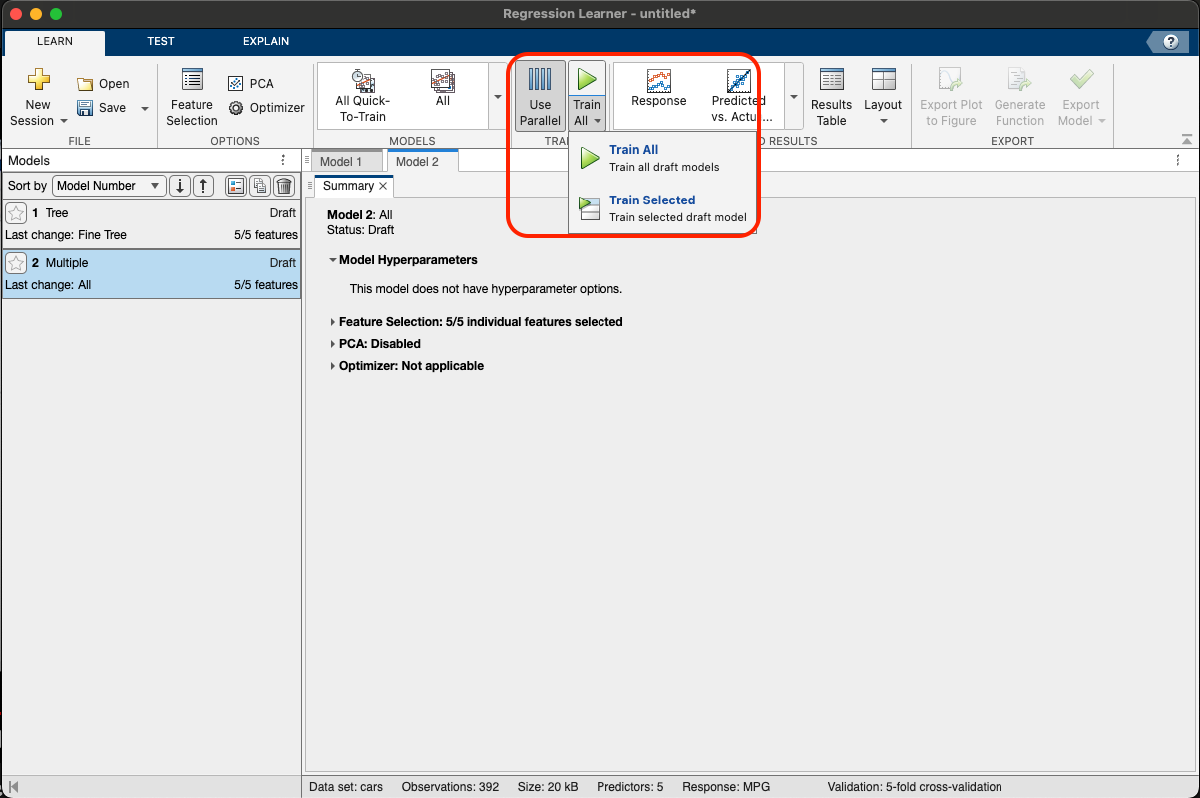

Wait until all the training has been completed. Select the model with the lowest RMSE for the Validation data set. In the EXPORT pane, click the drop down arrow and select 'Export Model' to export the model that we can use in this live script. 

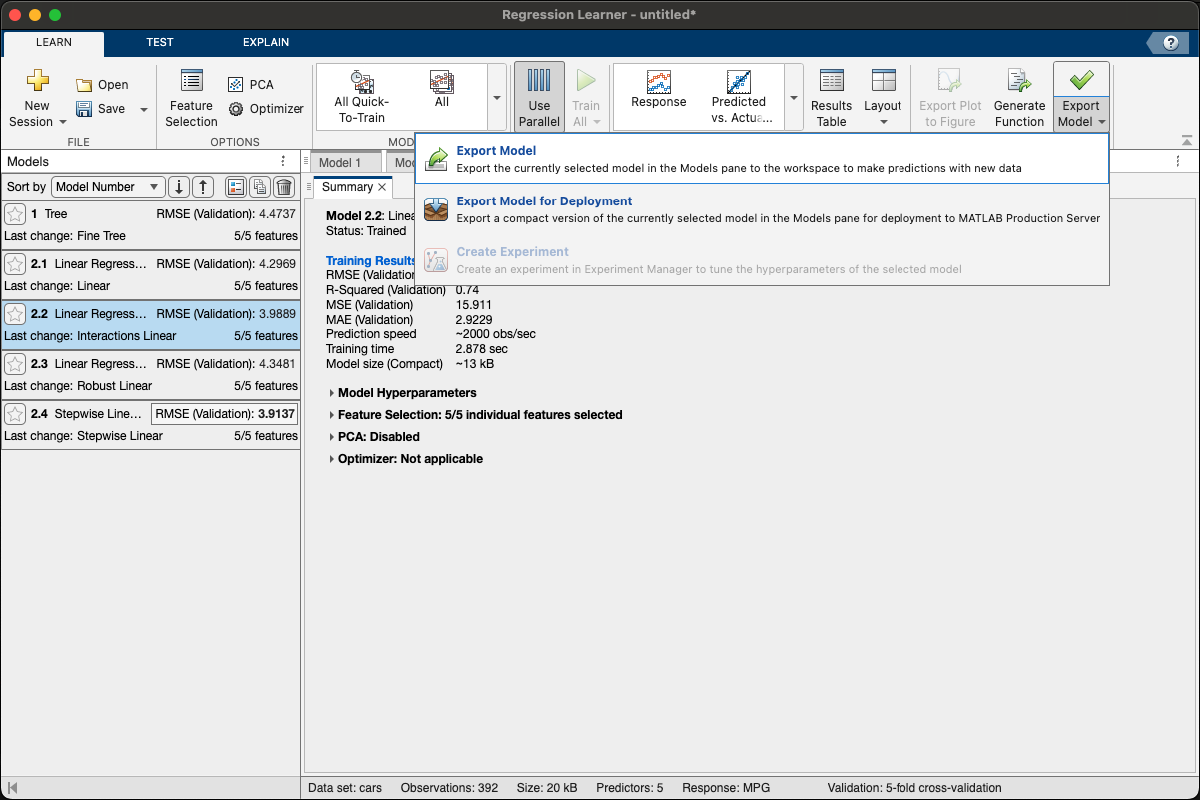

Keep the default name of the model 'trainedModel', and then click the OK button.

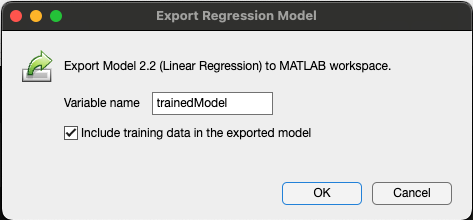

You can now see that a struct variable has been added to the Workspace. Run the code below to take a look at the model coefficients.

trainedModel.LinearModel.Coefficients.Estimate

Unlike our earlier approach which yielded five theta parameters and one bias, here MATLAB produced 15 theta parameters and one bias. The extra ten parameters are most probably from cross theta-terms and higher order theta parameters. 

## Functions Used

#### The Cost Function

This function computes for the cost function, $J\left(\theta_0 ,\theta_1 ,\ldotp \ldotp \ldotp ,\theta_n \right)$ with multiple features, with $x$, $y$, and $\theta$ as input variables and $Jcost$ as the output variable.

function [Jcost] = costfunction(x,y,theta)
    m = length(y);
    Jcost = (1/(2*m))*sum((x*theta-y).^2);
end

#### The Gradient Descent

This function computes for the new values of the parameter $\theta$ using the gradient descent method.

function [theta, J] = gradient_descent(x,y,theta,a,epoch)
    J = zeros(1,epoch);
    m = length(y);
    for k = 1:epoch
        grad_theta = (1/m)*x'*(x*theta-y);
        theta = theta - a*grad_theta;
        J(k) = costfunction(x,y,theta);
    end
end

#### Feature Scaling Function

This function rescales the elements of the data set.

function [Xfeat] = FeatureScale(X)
    Xmean = mean(X);                % mean
    Xstd = std(X);                  % standard deviation
    Xfeat = (X - Xmean)./(Xstd);
end